### **1. Set up the Project.**

Creating the necessairy directories and loading the names used to run the project.

The program then asks for the person's first name as well as the letter (vowel) they are going to record.

% Directories used in this project
audiofiles_directory_name = "audiofiles_lib\";
spectrogramfiles_directory_name = "spectrogramfiles_lib\";

% Check if the audiofiles directory exists
if ~isfolder(audiofiles_directory_name)
    mkdir(audiofiles_directory_name);
    fprintf('Directory "%s" created.\n', audiofiles_directory_name);
else
    fprintf('Directory "%s" already exists.\n', audiofiles_directory_name);
end

Directory "audiofiles_lib\" already exists.



% Check if the spectrogramfiles directory exists
if ~isfolder(spectrogramfiles_directory_name)
    mkdir(spectrogramfiles_directory_name);
    fprintf('Directory "%s" created.\n', spectrogramfiles_directory_name);
else
    fprintf('Directory "%s" already exists.\n', spectrogramfiles_directory_name);
end

Directory "spectrogramfiles_lib\" already exists.


### **2. Record data and store it in a .m4a file.**

This part of the program lets the user record a single letter and stores it after processing in a m4a file.

**Connect the Microphone.**

Fs = 48000; % Sampling Frequency
recObj = audiorecorder(Fs,16,1,1);

**Setup file names.**

person_name = input('Enter your first name: ', 's');
spoken_letter = input('Enter which vowel you are going to say: ', 's');
audiofile_name = audiofiles_directory_name + person_name + "_" + spoken_letter + ".m4a";
spectrogramfile_name = spectrogramfiles_directory_name + person_name + "_" + spoken_letter + ".png";
clear person_name; clear spoken_letter;
for i = 3:-1:1
    disp(i)
    pause(1)
end

     3

     2

     1



clear i;

**Record voice.**

recDuration = 1;
disp("Begin speaking.")

Begin speaking.


recordblocking(recObj,recDuration)
disp("End of recording.")

End of recording.


y = getaudiodata(recObj);
clear recDuration; clear recObj;

**Cut and save the recording.**

x = y(2.3e4:4.5e4, 1);
audiowrite(audiofile_name, x, Fs);
disp("audiofile saved successfully!")

audiofile saved successfully!


clear y; clear x;

### (optional) Display of the recorded sound

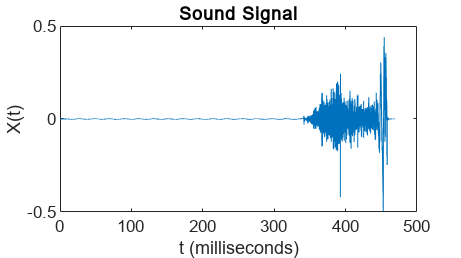

T = 1/Fs;                       % Sampling period 
x = audioread(audiofile_name);
L = size(x,1);                  % Length of signal
t = (0:L-1)*T;                  % Time vector

plot(1000*t,x)
title("Sound Signal");
xlabel("t (milliseconds)");
ylabel("X(t)");

clear x; clear t; clear T; clear L;

### **3. Creating the spectrogram using FFT**

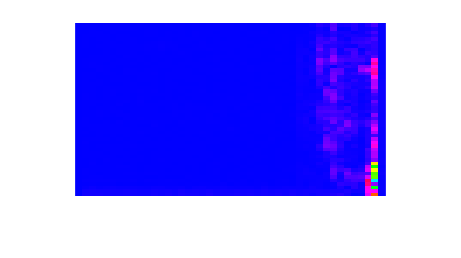

x = audioread(audiofile_name);              % audiofile
step_size = 500;                            % Amount of audio file readings per column
sample_size = 1000;                         % Amount of FFT samples (does NOT increase resolution!) >= step_size
       
M = FFT_Matrix(x,sample_size,step_size);
MC = FFT_Spectogram(M(1:50,:),40,10,5);  % over 50 on y-axis the amplitude is insigificantly low
img = flip(MC,1);                           % Origin (0,0) is bottom left corner
imshow(img)

imwrite(img,spectrogramfile_name)
disp("spectrogramfile saved successfully!")

spectrogramfile saved successfully!


clear x; clear M; clear freq; clear MC; clear img; clear step_size; clear sample_size;

#### (optional) Color gradient

leftmost colour: zero(min) , towards the right: max

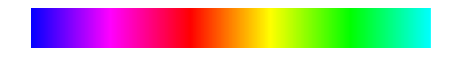

clear img;
img(1:500,1:10,1:3) = 1;

for n = 1:500
    pic = double2rgb(n,500);
    t = n*10;
    img(1:500,(t+1):(t+10),1) = pic(1);
    img(1:500,(t+1):(t+10),2) = pic(2);
    img(1:500,(t+1):(t+10),3) = pic(3);
end
imshow(img)

clear n; clear t; clear pic; clear img;

## Our own functions

### Linear colour gradient

(basic principle)

function result = linear_gradient(val,period,type_size)
    val_mod = mod(val,(6*period));

    if (0 <= val_mod) && (val_mod < period)
        result = (type_size*val_mod)/period;

    elseif (period <= val_mod) && (val_mod < 3*period)
        result = type_size;

    elseif (3*period <= val_mod) && (val_mod < 4*period)
        result = (type_size-(type_size*((val_mod+1)-4*period)))/period;

    elseif (4*period <= val_mod) && (val_mod < 6*period)
        result = 0;

    end
end

### Convert amplitude to colour

blue at amp = 0 and cyan at amp = max, if larger then max goes back to blue 

function result = double2rgb(amp,max)
    spec = [0 0 0];
    period = max/5;
    type_size = 1;      % double = 1 , uint8 = 255
    
    spec(1) = linear_gradient(amp,            period, type_size);
    spec(2) = linear_gradient(amp + 4*period, period, type_size);
    spec(3) = linear_gradient(amp + 2*period, period, type_size);

    result = spec;
end

### FFT in timeintervals saved in matrix

y-axis : frequency

x-axis : time

function M = FFT_Matrix(Signal,sample_size,step_size)

    Xb(1:sample_size ,1) = 0;
    M(1:((sample_size/2)+1),1:round(size(Signal)/step_size)) = -1;
    
    for n = 1:round(size(Signal)/step_size)
    step = (n-1) * step_size;
    Xb(1:step_size,1) = Signal(step+1:step+step_size,1);    %isolate the amount(step_size) of audio readings rest is filled with 0
    Yb = fft(Xb);                                           %convert step_size(timeinterval) with fft
    M(1:((sample_size/2)+1),n) = abs(Yb(1:((sample_size/2)+1)));    %save only half of the calculated values, fourie spectrum in mirrored after the first half
    end
end

#### FFT_Matrix converted to spectogram

function MC = FFT_Spectogram(FFT_Matrix,Max_Amp,sizeX,sizeY)

    MC(1:size(FFT_Matrix,1)*sizeY,1:size(FFT_Matrix,2)*sizeX,1:3) = -1;
    Colour(1:3) = -1;
    for n = 0:size(FFT_Matrix,1)-1
        for m = 0:size(FFT_Matrix,2)-1
            Colour(1:3) = double2rgb(FFT_Matrix(n+1,m+1),Max_Amp);  %calculate colour
            % create a sizeX*sizeY rectangle of this colour
            MC((n*sizeY:(n*sizeY)+sizeY)+1,(m*sizeX:(m*sizeX)+sizeX)+1,1) = Colour(1);
            MC((n*sizeY:(n*sizeY)+sizeY)+1,(m*sizeX:(m*sizeX)+sizeX)+1,2) = Colour(2);
            MC((n*sizeY:(n*sizeY)+sizeY)+1,(m*sizeX:(m*sizeX)+sizeX)+1,3) = Colour(3);
        end
    end
end